# Optimierung der Rotorparameter

clear all

Parameter

%       xD1     xB2     xD2     Ra      R1      R2      b1      b2      L
x0 = [  0.6     0.70    0.85    0.0085  0.05    0.08    0.015   0.015   1.0     ]; 
xL = [  0.05    0.55    0.70    0.0085  0.01    0.01    0.01    0.01    1.0     ];  % untere Schranke
xU = [  0.80    0.90    0.99    0.012   0.09    0.09    0.025   0.025   1.1     ];  % obere Schranke

Drehzahl

Omega = 600/60*2*pi;

### Optimierung der Parameter

Zielfunktion

objFun = @(x)RotModAna(x,Omega);

Zwangsbedingung (Postion rechtes Auflager und die zwei Scheiben)

A = zeros(2,9);
A(1,1) = 1; A(1,2) = -1;    b(1) = -0.05;
A(2,2) = 1; A(2,3) = -1;    b(2) = -0.05;

Optimierung

x = fmincon(objFun,x0,A,b,[],[],xL,xU)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0500    0.7757    0.8257    0.0085    0.0900    0.0900    0.0250    0.0250    1.0000


### Campbell Diagramm

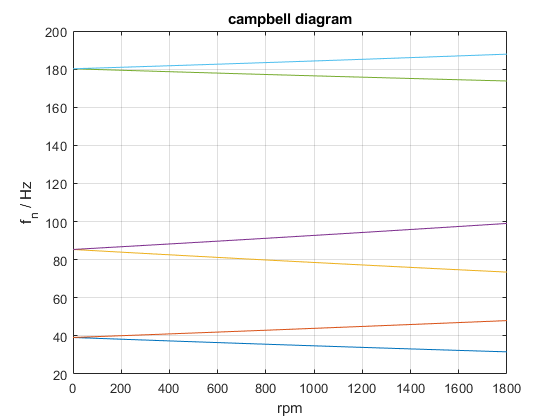


rpm = 0:100:1800;

for i=1:length(rpm)
    [~,fn] = RotModAna(x,rpm(i)/60*2*pi);
    fnM(i,:) = fn(1:6)';
end

plot(rpm',fnM')
grid on
xlabel 'rpm'
ylabel 'f_n / Hz'
title 'campbell diagram'

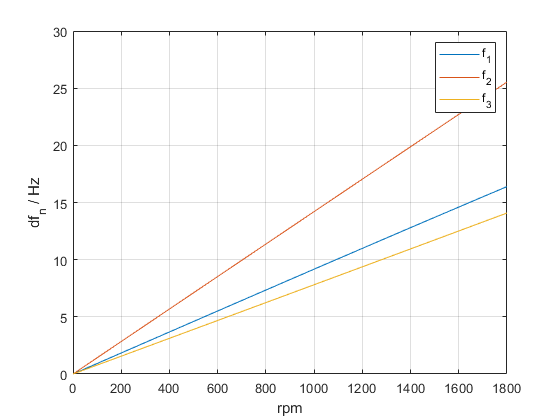


df = [ fnM(:,2)-fnM(:,1)  fnM(:,4)-fnM(:,3)  fnM(:,6)-fnM(:,5) ];
plot(rpm',df')
grid on
xlabel 'rpm'
ylabel 'df_n / Hz'
legend ({'f_1','f_2','f_3'})

RotModAna(x0,Omega);